# Lab Assignment 3: Solving Systems of Differential Equations

**Submission instructions:** Export your completed MLX file as a PDF, and upload both this MLX file and the PDF export in one submission to Gradescope.

## Useful Commands

## **The Tacoma Narrows Bridge **

One famous application of eigenvalues and eigenvectors can be found in determining the resonant frequency of a spring mass system. For example, in the [Tacoma Narrows Bridge collapse](https://youtu.be/mXTSnZgrfxM?t=203) during the year 1940, scientists analyzed the system and one hypothesis for the cause of such a catastrophic failure was that the way wind moved through the bridge caused it to oscillate stronger and stronger at its natural, resonant frequency. 

In this assignment, we'll be using linear algebra principles to model resonant dynamics in a mass-spring bridge model.

### Hooke's law

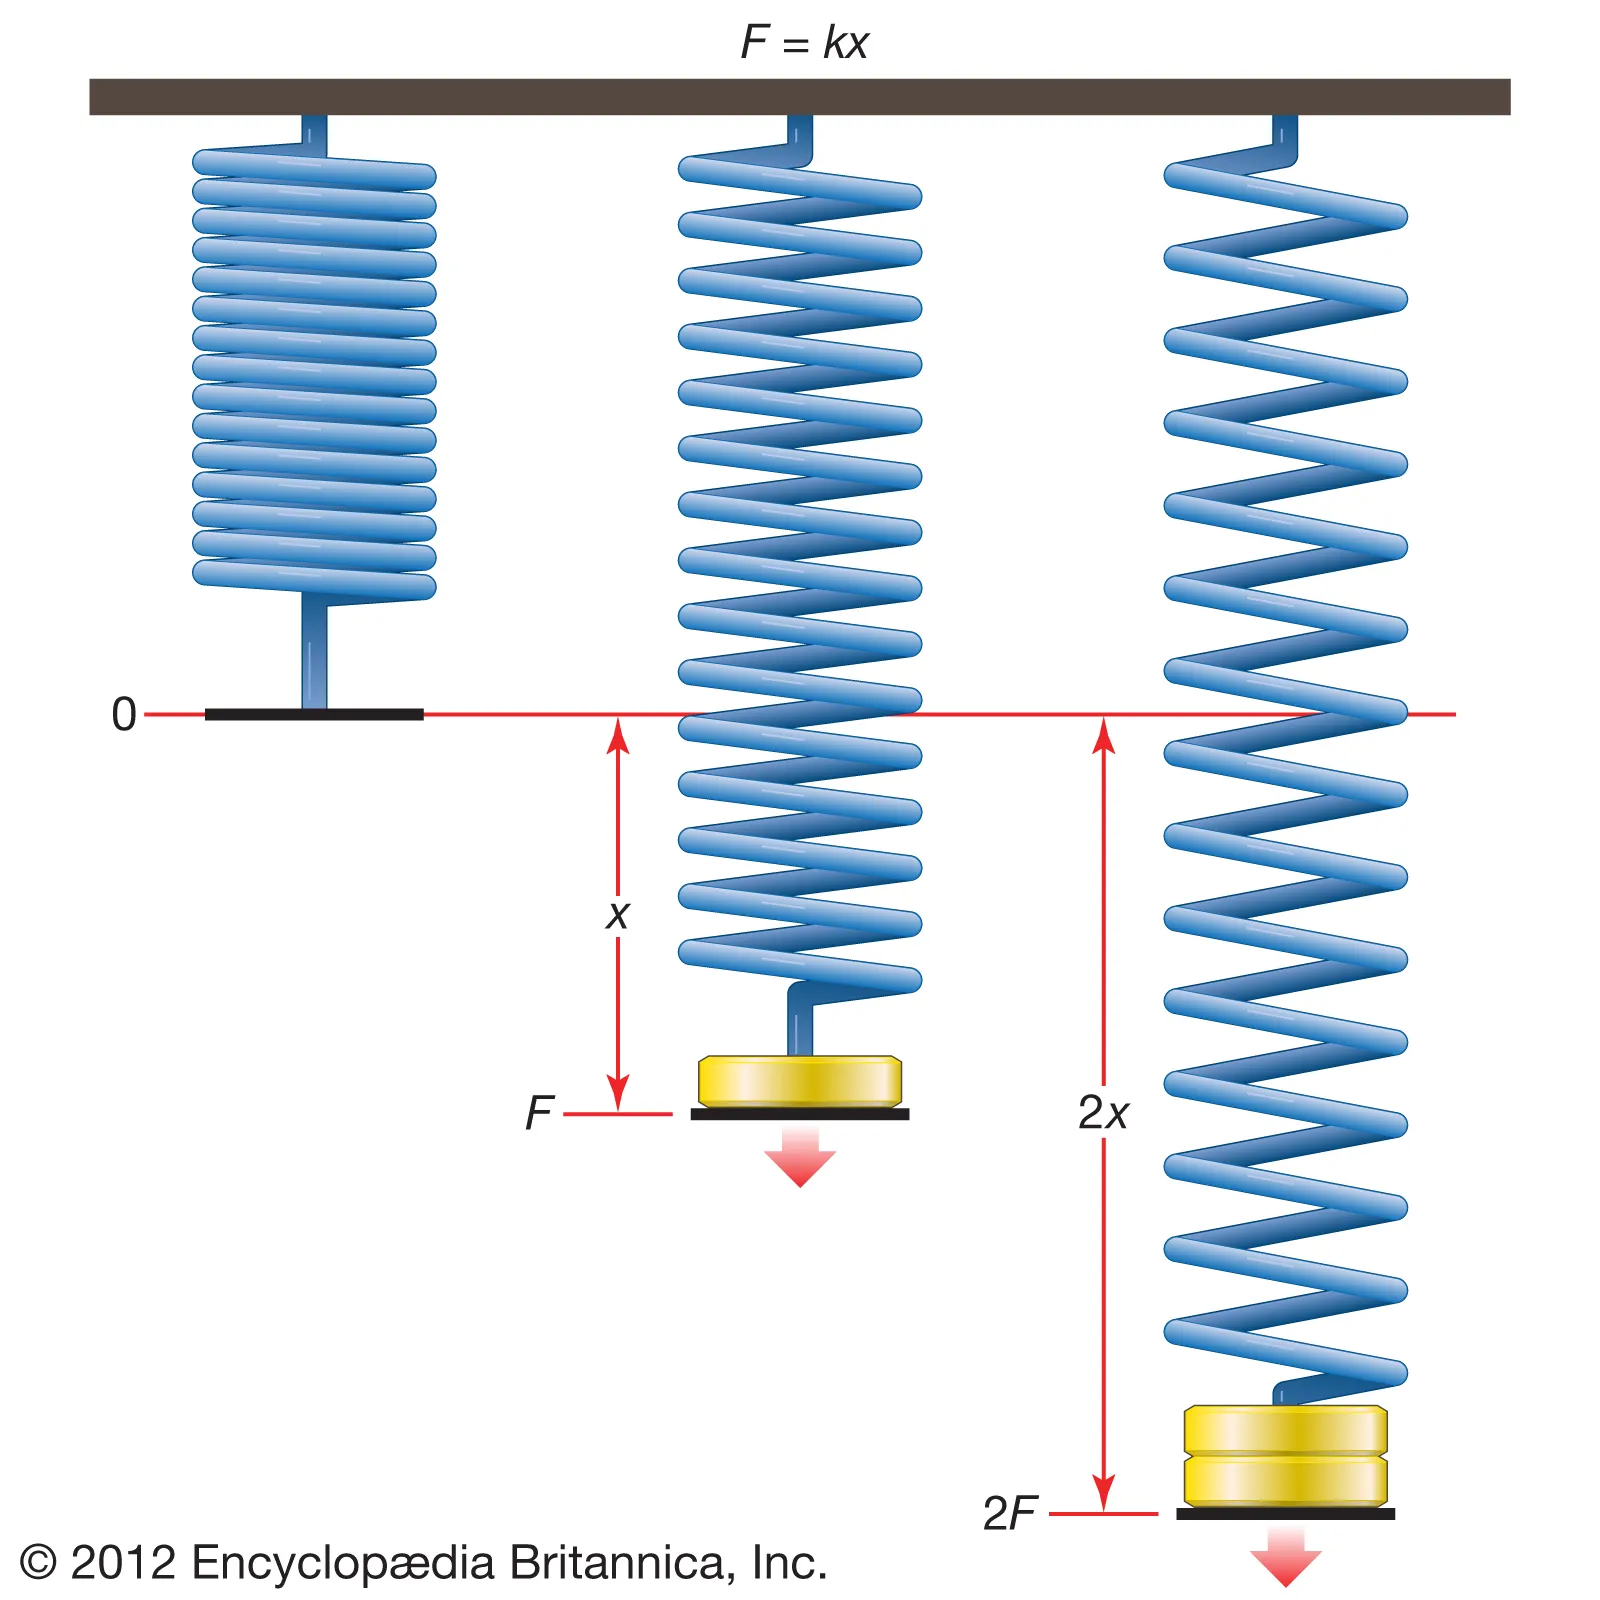

Hooke's law states that in simple, non-deformable, elastic materials: the force applied is proportional to the extension.

Mathematically, this can be represented as $F_s =k\cdot x$ where:

        $F_s$ is the force exerted by the object

        $x$ is the extension or compression of the material, with respect to its neutral position

        $k$ is the spring constant, a property of the material

Hooke's law, naturally, applies to springs. But also to many other objects like metal beams which are used in bridges!

## Problem 1: Using OLS to estimate the spring constant

During construction, engineers measured the deflection of the bridge when it is loaded it with a known mass.

The data consists of the measured deflection in mm ($x$) based on the load on the bridge measured in kg ($F$), and is available at [https://raw.githubusercontent.com/dtxe/mat188_datasets/main/bridge_measurements.csv](https://raw.githubusercontent.com/dtxe/mat188_datasets/main/bridge_measurements.csv)

Recall:

- A 0th order model is $f\left(x\right)=c_0$, a 1st order model is $f\left(x\right)=c_0 +c_1 x$, and 2nd order model is$f\left(x\right)=c_0 +c_1 x+c_2 x^2$

- The tabular data you loaded gives you a number of data points, i.e., $\left(a_1 ,b_1 \right)$,$\left(a_2 ,b_2 \right)$,$\left(a_3 ,b_3 \right)$, etc.

- Using #1 and #2, we can write a system of equations, $A\left\lbrack \begin{array}{c}
c_0 \\
c_1 \\
\cdots 
\end{array}\right\rbrack =\vec{b}$, and find the least-squares approximation, $\vec{c^* } =\left\lbrack \begin{array}{c}
c_0^* \\
c_1^* \\
\cdots 
\end{array}\right\rbrack ={\left(A^T A\right)}^{-1} A^T \vec{b}$.

For example, in the following figure we can see that our least-square approximation is a quadratic function, $f^* \left(x\right)$, and it fits the data points, $\left(a_1 ,b_1 \right)$,$\left(a_2 ,b_2 \right)$,$\left(a_3 ,b_3 \right)$, and $\left(a_4 ,b_4 \right)$, well.

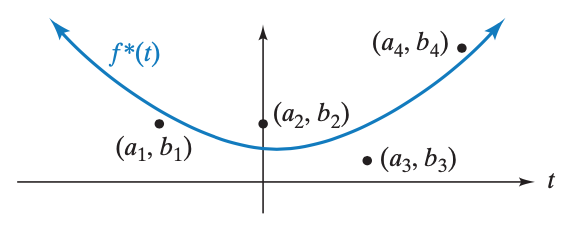

For a more detailed explanation about Ordinary Least Squares please refer to Chapter 5.4 in the textbook.

**Load in the experimental measurement data. **

data = readtable('https://raw.githubusercontent.com/dtxe/mat188_datasets/main/bridge_measurements.csv');

**Use matrices to perform Ordinary Least Squares to estimate the 0th order (constant), 1st order (linear) and 2nd order (quadratic) models.**

- For this assignment, do not use MATLAB's built-in regression functions. You may, however, double-check your work by comparing it to the output of MATLAB's built-in functions.

springData = table2array(data);
b = springData(:,2);
[row,col] = size(springData);

A_0 = ones(row,1);              %matrix for the 0th order model
coefs0 = inv(A_0'*A_0)*A_0'*b   %coefficients for the 0th order model

coefs0 = 23.2829


A_1 = ones(row,1);
A_1 = [A_1 springData(:,1)];    %matrix for the 1st order model
coefs1 = inv(A_1'*A_1)*A_1'*b   %coefficients for the 1st order model

coefs1 =     0.8274
    0.0009



A_2 = ones(row,1);
x_2= [];
for k = (1:row)
    x_2 = [x_2; springData(k,1)^2];
end
A_2 = [A_2 springData(:,1) x_2]; %matrix for the 2nd order model
coefs2 = inv(A_2'*A_2)*A_2'*b    %coefficients for the 2nd order model

coefs2 =    -0.3292
    0.0010
   -0.0000


**On the same axes, plot the raw data points from the file, overlaid with all of the three models in different colours.**

- Make sure you label your axes, include a plot title, and add a legend with sensible labels!

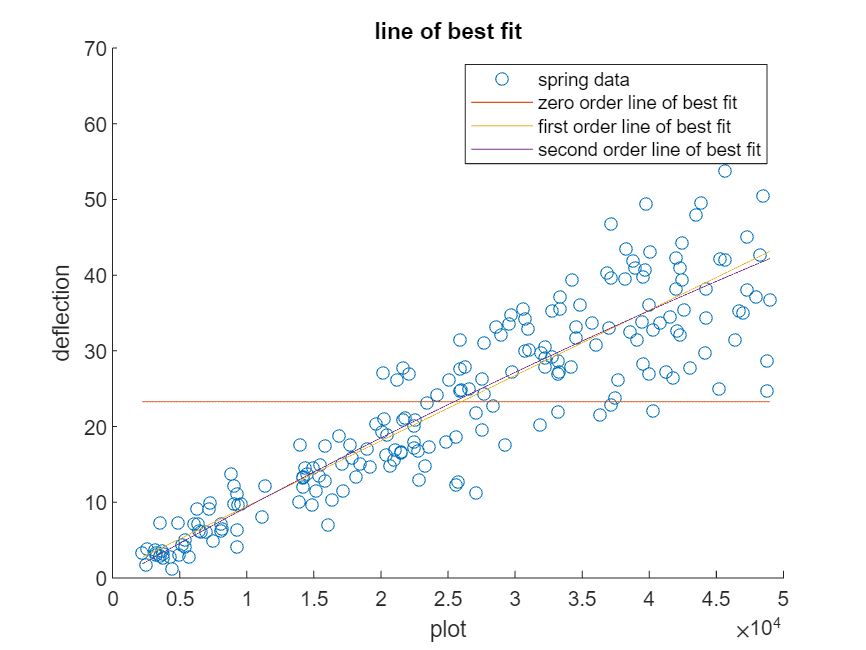

x = springData(:,1);
y = springData(:,2);

regressionvalue = [min(springData):0.1:max(springData)]';
y0 = [ones(length(regressionvalue),1)]*coefs0;                              % y values for the 0th order model
y1 = [ones(length(regressionvalue),1),regressionvalue]*coefs1;              % y values for the 1st order model
y2 = [ones(length(regressionvalue),1),regressionvalue,regressionvalue.^2]*coefs2;   % y values for the 2nd order model

hold on
scatter(x,y)                % spring data points
plot(regressionvalue,y0)    % 0th order
plot(regressionvalue,y1)    % 1st order
plot(regressionvalue,y2)    % 2nd order
xlabel('plot')
ylabel('deflection')
title('line of best fit')
legend('spring data','zero order line of best fit', 'first order line of best fit','second order line of best fit')
hold off

Many materials are non-deformable and elastic for typical forces, and therefore, follow Hooke's law. However, some special materials, or materials loaded with relatively extreme forces may exhibit a non-linear relationship between deflection and exerted force.

**By visual inspection of the model outputs, which model provides the best fit for the data? In other words, what's the minimum order of the model (0th, 1st, or 2nd order) that adequately captures most of the dependent variation in the data based on the plot? Why do you think so?**

**        Your answer: **The first order model gives the best line of fit for the data**. **Based on the model above, the points are increasing linearly. The second order model which is a quadratic least squares regression model is almost the asme as the first-order model because the quadratic coefficent is very close to 0.  

**Based on this assessment, does the bridge follow Hooke's law for the series of test masses that were used?**

**        Your answer: **The bridge does follow Hooke's law for the test masses used. The equation for Hooke's Law is linear, so the first-order model for the data makes the most sense. 

Note: in this assignment we are visually comparing whether the constant, linear, or quadratic fits match the data best.  In future courses, you will learn about mathematical ways to evaluate goodness-of-fit that we will not presently address.

**Assuming the bridge does follow Hooke's law, use the first-order model you developed to find the spring coefficient of the bridge using Hooke's Law (**$F=k\cdot x$**).**

- Retrieve or compute this value from variables in the workspace; do not enter it manually.

- Print "`The spring constant of the bridge is 0.00e0`" where `0.00e0` is replaced by the estimated empirical spring constant derived from your OLS model, expressed in scientific notation.

springConstant = 9.81*1000/coefs1(2,1)

springConstant = 1.1358e+07

fprintf('The spring constant of the bridge is %0.2e N/m.',springConstant)

The spring constant of the bridge is 1.14e+07 N/m.

## **Modelling the Tacoma Bridge as a mass-spring system**

In this assignment, we are going to investigate the prerequisite material required to understand the motion of spring body systems using differential equations, eigenvalues, and eigenvectors and try to understand a much simplified model of the Tacoma bridge. 

Suppose we model part of a horizontal suspension system supporting the Tacoma Bridge as a collection of two small masses *m *surrounding a central mass *M *that are connected through two springs with spring constant *k*.

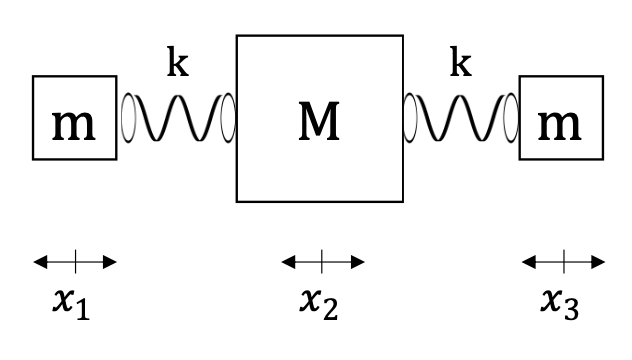

Based on Hooke's Law ($F=k\cdot x$) and Newton's Second Law ($F=m\cdot a=m\cdot \frac{d^2 }{\mathrm{d}t^2 }x$), the three dynamic equations that describe the motion of the three individual masses:

            
$$m\cdot \frac{d^2 }{\mathrm{d}t^2 }x_1 =k\left(x_2 -x_1 \right)$$


            
$$M\cdot \frac{d^2 }{\mathrm{d}t^2 }x_2 =k\left(x_1 +x_3 -2x_2 \right)$$


            
$$m\cdot \frac{d^2 }{\mathrm{d}t^2 }x_3 =k\left(x_2 -x_3 \right)$$


We will write this set of equations in matrix form and then reformulate it as an eigenvalue problem. This will give us a convenient way to solve this system of differential equations. 

            
$$\left\lbrack \begin{array}{c}
\frac{d^2 }{\mathrm{d}t^2 }x_1 \\
\frac{d^2 }{\mathrm{d}t^2 }x_2 \\
\frac{d^2 }{\mathrm{d}t^2 }x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\frac{k}{m} & \frac{k}{m} & 0\\
\frac{k}{M} & -\frac{2k}{M} & \frac{k}{M}\\
0 & \frac{k}{m} & \frac{-k}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


## Problem 2: Using ODEs to represent the mass-spring system

To solve for any potential resonant (ie. oscillatory) frequencies of the bridge, assume there is some periodic solution: 

            
$$x\left(t\right)=c\nu \;\cos \left(\omega t+\phi \right)$$


where $x$ is the position vector of the three masses, $c$ is a constant that depends on the initial value of the position, $v$ is an unknown vector, $\omega$ is the natural frequency of oscillation, and $\phi$ is the phase of oscillation.

**Write the presumptive oscillatory solution in MATLAB using symbolic math, then take the second derivative w.r.t. **$t$**.**

        **Hint:** Refer to the useful functions section above!

clear A m M
syms c v omega phi t x(t)
x(t) = c*v*cos(omega*t + phi)

$$x(t) = c\,v\,\cos\left(\varphi +\omega \,t\right)$$

derivative_second = diff(x(t),t,2)

$$derivative\_second = -c\,\omega^{2}\,v\,\cos\left(\varphi +\omega \,t\right)$$

Notice that with this assumption, $\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x\left(t\right)=-\omega^2 \cdot x\left(t\right)$.

Therefore, assuming an oscillatory response and substituting $x\left(t\right)$ and $\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x\left(t\right)$ into our matrix equation, we obtain:

            
$$-\omega^2 \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\frac{k}{m} & \frac{k}{m} & 0\\
\frac{k}{M} & -\frac{2k}{M} & \frac{k}{M}\\
0 & \frac{k}{m} & \frac{-k}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$


Reformulating this matrix equation into the eigenvector problem $\textrm{Ax}=\lambda x$.

            
$$\left\lbrack \begin{array}{ccc}
\frac{k}{m} & -\frac{k}{m} & 0\\
-\frac{k}{M} & \frac{2k}{M} & -\frac{k}{M}\\
0 & -\frac{k}{m} & \frac{k}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\lambda \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$
 

**Write matrix **$A$** symbolically in MATLAB code:**

syms k m M
A = [k/m, -k/m, 0;
    -k/M, 2*k/M, -k/M;
    0, -k/m, k/m;]

$$A = \left(\begin{array}{ccc} \frac{k}{m} & -\frac{k}{m} & 0\\ -\frac{k}{M} & \frac{2\,k}{M} & -\frac{k}{M}\\ 0 & -\frac{k}{m} & \frac{k}{m} \end{array}\right)$$

## Problem 3: Using eigenvectors and eigenvalues to solve the system of ODEs

**Compute the eigenvalues and eigenvectors of **$A$** using the **`eig`** function.**

    **Hint:** Refer to the useful functions section at above!

[V,D] = eig(A)

$$V = \left(\begin{array}{ccc} 1 & -1 & 1\\ 1 & 0 & -\frac{2\,m}{M}\\ 1 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{k}{m} & 0\\ 0 & 0 & \frac{M\,k+2\,k\,m}{M\,m} \end{array}\right)$$

eig_vec_1 = V(:,1)

$$eig\_vec\_1 = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

eig_vec_2 = V(:,2)

$$eig\_vec\_2 = \left(\begin{array}{c} -1\\ 0\\ 1 \end{array}\right)$$

eig_vec_3 = V(:,3)

$$eig\_vec\_3 = \left(\begin{array}{c} 1\\ -\frac{2\,m}{M}\\ 1 \end{array}\right)$$

eig_values = diag(D)

$$eig\_values = \left(\begin{array}{c} 0\\ \frac{k}{m}\\ \frac{M\,k+2\,k\,m}{M\,m} \end{array}\right)$$

**Using your eigenvalues, determine the values of **$\omega$** that solve this system of equations.**

w = sqrt(eig_values)

$$w = \left(\begin{array}{c} 0\\ \sqrt{\frac{k}{m}}\\ \sqrt{\frac{M\,k+2\,k\,m}{M\,m}} \end{array}\right)$$

**For the following parameters, compute the oscillatory modes of the bridge in Hz, and print it to exactly 5 decimal places.**

            $k=$ *from Part 1*, $m={10}^3$, $M={10}^6$

**Hint:  **$f=\frac{\omega }{2\pi }$

clear k m M
m = 10^3;
M = 10^6;
k = 9.81*1000/coefs1(2,1);

w2 = [0, k/m, (M*k+2*k*m)/(M*m)];
w = sqrt(w2);
f = w/(2*pi)

f =          0   16.9620   16.9789


f1 = f(1,1);
f2 = f(1,2);
f3 = f(1,3);

fprintf("The oscillatory modes are %.5f Hz, %.5f Hz, and %.5f Hz", f1, f2, f3)

The oscillatory modes are 0.00000 Hz, 16.96198 Hz, and 16.97893 Hz

For the oscillatory mode described by the eigenvalue and eigenvector below, describe the motion of the center mass for this oscillatory mode on its own, in one sentence. 

            
$$\lambda =\frac{k}{m},A=\left\lbrack \begin{array}{c}
-1\\
0\\
1
\end{array}\right\rbrack$$


**Your answer: **Since the second component of A is 0, the central mass will not move. 

*Well done! Congratulations on completing the MATLAB portion of the MAT188 course!*